# 测试

clc
clear
close all
addpath("src\");

## C-W交会

n = 0.00111; % rad/s
tf = 2000.; % s
x0 = [2200., 8000., 100., 0., 0., 0.]';  % m, m/s
xf = zeros(6, 1);
step = 1;

### 双脉冲

[dv, dv0, ~] = Cw2Impulse(n, x0, tf, xf)

dv =     7.6600    4.9969    2.6630


dv0 =     1.4451
   -4.7827
    0.0842


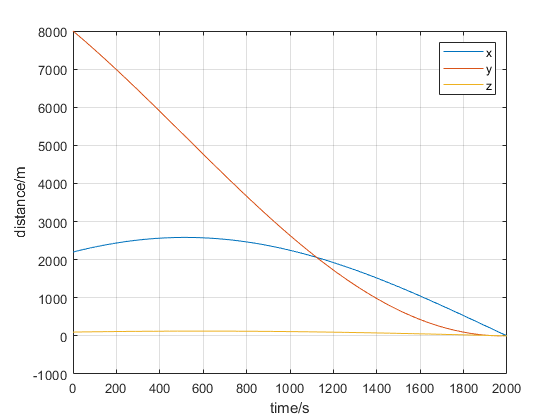

args.n = n;
r = x0(1 : 3);
v = x0(4 : 6) + dv0;
[t, x] = ode45(@(t, x) CwEq(t, x, zeros(3, 1), args), 0 : step : tf, [r; v]);
plot(t, x(:, 1 : 3))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')

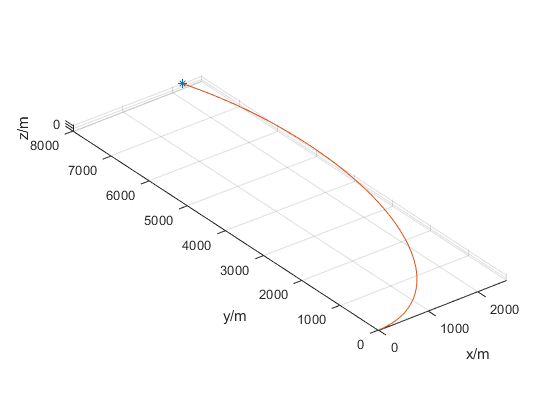

figure
plot3(x0(1), x0(2), x0(3), '*')
hold on
plot3(x(:, 1), x(:, 2), x(:, 3))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

### 多脉冲转连续推力

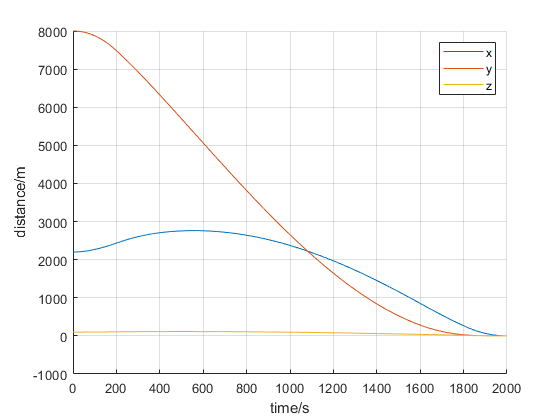

dt = 200;
t1 = 0;
t2 = tf;
x1 = x0;
x2 = xf;
s0 = [];
sf = [];
for i = 1 : tf / dt / 2
    [~, dv0, dvf] = Cw2Impulse(n, x1, t2(end) - t1(end), x2);
    u0 = dv0 / dt;
    uf = dvf / dt;
    [t1, s1] = ode45(@(t, x) CwEq(t, x, u0, args), t1(end) + (0 : step : dt), x1);
%     plot(t1, s1(:, 1), 'b', t1, s1(:, 2), 'r', t1, s1(:, 3), 'y')
    [t2, s2] = ode45(@(t, x) CwEq(t, x, uf, args), t2(end) - (0 : step : dt), x2);
%     plot(t2, s2(:, 1), 'b', t2, s2(:, 2), 'r', t2, s2(:, 3), 'y')
    x1 = s1(end, :)';
    x2 = s2(end, :)';
    s0 = [s0(1 : end - 1, :); t1, s1, [u0', norm(u0)] .* ones(length(t1), 1)];
    sf = [sf(1 : end - 1, :); t2, s2, [uf', norm(uf)] .* ones(length(t2), 1)];
end
s = [s0; flip(sf(1 : end - 1, :))];
figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

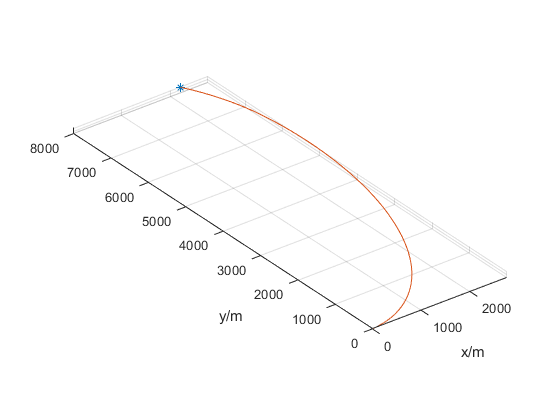

figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

figure
hold on
plot(s(:, 1), s(:, 8 : 11))
grid on
legend('u_x', 'u_y', 'u_z', 'u')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off

### 高斯伪谱法

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      92    2.000000e+03    7.854e+02    9.997e-01
    1     184    1.998999e+03    7.921e-02    9.997e-01    1.118e+01
    2     276    1.997993e+03    2.036e-03    9.997e-01    1.006e+00
    3     368    1.992963e+03    5.072e-02    9.997e-01    5.031e+00
    4     460    1.967811e+03    1.275e+00    9.996e-01    2.515e+01
    5     552    1.842083e+03    3.273e+01    9.992e-01    1.257e+02
    6     645    1.601210e+03    1.120e+02    9.891e-01    2.409e+02
    7     737    1.600006e+03    1.118e+02    9.586e-01    1.204e+00
    8     829    1.600125e+03    8.295e-03    1.253e-01    2.693e-01
    9     921    1.600100e+03    1.877e-06    1.000e-01    2.539e-02
   10    1013    1.600020e+03    2.005e-05    2.000e-02    8.012e-02
   11    1105    1.600000e+03    1.223e-06    2.001e-04    1.977e-02
   12    1197    1.600000e+03    1.546e-10    2

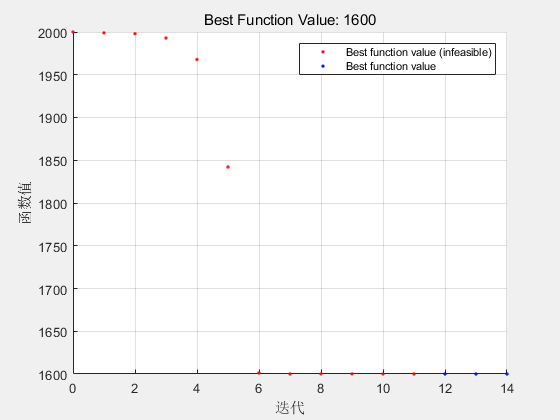


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


args.n = 0.00111; % rad/s
tf = 2000.; % s
x0 = [2200., 8000., 100., 0., 0., 0.]';  % m, m/s
xf = zeros(6, 1);
lb = [-1000, -1000, -100, -10, -10, -1, -0.5, -0.5, -0.1, 0.1 * tf];
ub = [3000, 9000, 200, 10, 10, 1, 0.5, 0.5, 0.1, 1.2 * tf];
[s, x_nlp, fval, exitflag, output, lambda, ct] = Gpm(x0, xf, @CwEq, s, lb, ub, 10, args);

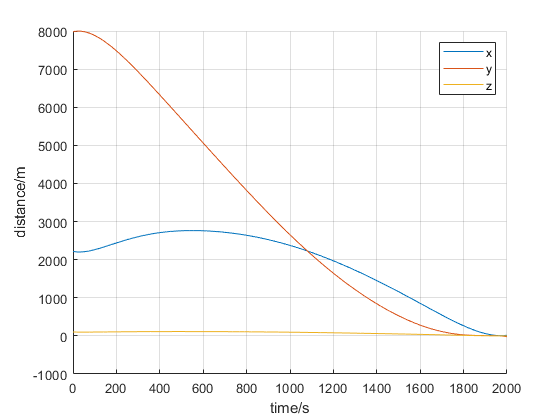

tf = x_nlp(end);
figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

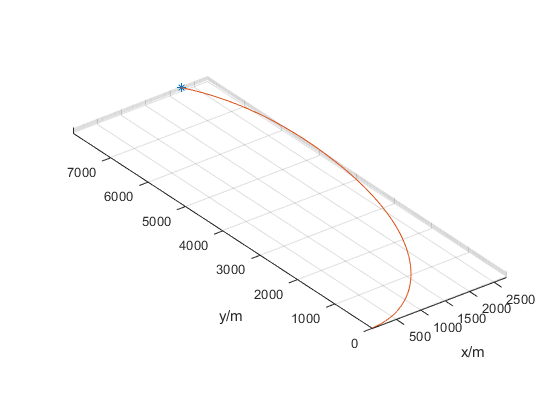

figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

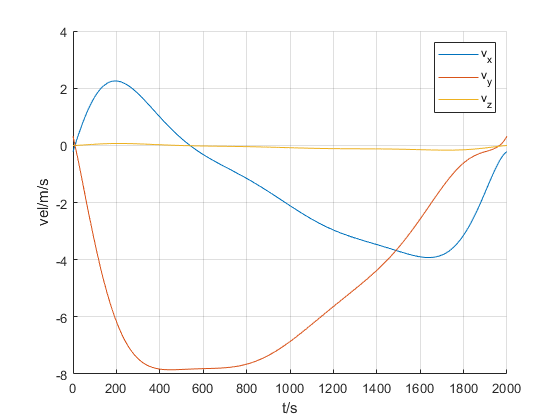

figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

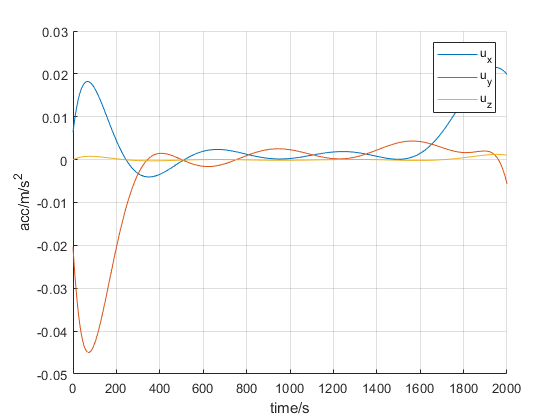

figure
hold on
plot(s(:, 1), s(:, 8 : 10))
grid on
legend('u_x', 'u_y', 'u_z')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off

## 连续推力

### 间接法

tic
% [t, x] = CwIndirOpt(x0, n, tf, step, 'Riccati');
[t, x] = CwIndirOpt(x0, n, tf, step);

lambda0 = [

-1.03709925546575e-05;

-7.64011415818231e-06;

1.10740639139064e-07;

0.00233724163211481;

-0.0101864047861809;

3.64140230123426e-05];

toc
figure
plot3(x0(1), x0(2), x0(3), '*')
hold on
plot3(x(:, 1), x(:, 2), x(:, 3))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off
figure
hold on
plot(t, x(:, 1))
plot(t, x(:, 2))
plot(t, x(:, 3))
grid on
legend('x', 'y', 'z')
xlabel('t/s')
ylabel('dis/m')
hold off
figure
hold on
plot(t, x(:, 4))
plot(t, x(:, 5))
plot(t, x(:, 6))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off
figure
hold on
plot(t, x(:, 7))
plot(t, x(:, 8))
plot(t, x(:, 9))
a = zeros(length(t), 1);
for i = 1 : length(t)
    a(i) = norm(x(i, 7 : 9));
end
plot(t, a)
grid on
legend('a_x', 'a_y', 'a_z', 'a_{total}')
xlabel('t/s^2')
ylabel('acc/m')
hold off
sum(a) / length(t) * tf

### 直接法

tic
% [t, x] = CwDirOpt(x0, n, tf, step, 11);
toc
figure
plot3(x0(1), x0(2), x0(3), '*')
hold on
plot3(x(:, 1), x(:, 2), x(:, 3))
grid on
axis equal
xlabel('x')
ylabel('y')
zlabel('z')
hold on
figure
hold on
plot(t, x(:, 1))
plot(t, x(:, 2))
plot(t, x(:, 3))
grid on
legend('x', 'y', 'z')
xlabel('t/s')
ylabel('dis/m')
hold off
figure
hold on
plot(t, x(:, 4))
plot(t, x(:, 5))
plot(t, x(:, 6))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off
figure
hold on
plot(t, x(:, 7))
plot(t, x(:, 8))
plot(t, x(:, 9))
a = zeros(length(t), 1);
for i = 1 : length(t)
    a(i) = norm(x(i, 7 : 9));
end
plot(t, a)
grid on
legend('a_x', 'a_y', 'a_z', 'a_{total}')
xlabel('t/s^2')
ylabel('acc/m')
hold off
sum(a) / length(t) * tf

## 固定推力

x0 = [-2200., -8000., 100., 0., 0., 0.]';  % m, m/s
tf = 2000.; % s
n = 0.00111; % rad/s
tspan = 1;
f = 0.02; % m/s^2

### 间接法

tic
% [t, x] = CwIndirOpt3(x0, n, f, tf, tspan);
toc
figure
plot3(x0(1), x0(2), x0(3), '*')
hold on
plot3(x(:, 1), x(:, 2), x(:, 3))
grid on
axis equal
xlabel('x')
ylabel('y')
zlabel('z')
hold on
figure
hold on
plot(t, x(:, 1))
plot(t, x(:, 2))
plot(t, x(:, 3))
grid on
legend('x', 'y', 'z')
xlabel('t/s')
ylabel('dis/m')
hold off
figure
hold on
plot(t, x(:, 4))
plot(t, x(:, 5))
plot(t, x(:, 6))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off
figure
hold on
plot(t, x(:, 7))
plot(t, x(:, 8))
plot(t, x(:, 9))
a = zeros(length(t), 1);
for i = 1 : length(t)
    a(i) = norm(x(i, 7 : 9));
end
plot(t, a)
grid on
legend('a_x', 'a_y', 'a_z', 'a_{total}')
xlabel('t/s^2')
ylabel('acc/m')
hold off
sum(a) / length(t) * tf